clear all
close all
load RRR_data.mat

## Calcolo punti con linspace 

Npoint=1e8;
N1=ceil(Npoint^(1/3));
N2=ceil(Npoint^(1/3));
N3=ceil(Npoint^(1/3));
point=zeros(4,Npoint);
i=1;
for q1 = linspace(-Con(1,1),Con(1,1),N1)
    for q2 = linspace(-Con(1,2),Con(1,2),N2)
        for q3 = linspace(-Con(1,3),Con(1,3),N3)
            point(:,i)=RRR_cinDir([q1 q2 q3]',link);
            i=i+1;
        end
    end
end

## Save punti

save RRR_wk_points point

## Calcolo minimi & massimi

load RRR_wk_points.mat
div=200;
Xdiv=div;Ydiv=div;Zdiv=div;
xmax=max(point(1,:));
xmin=min(point(1,:));
ymax=max(point(2,:));
ymin=min(point(2,:));
zmax=max(point(3,:));
zmin=min(point(3,:));
X=linspace(xmin,xmax,Xdiv);
dx=X(2)-X(1);
Y=linspace(ymin,ymax,Ydiv);
dy=Y(2)-Y(1);
Z=linspace(zmin,zmax,Zdiv);
dz=Z(2)-Z(1);

## Ricerca superficie metodo2

space=zeros(Xdiv,Ydiv,Zdiv);
for p=point
    x=p(1);
    y=p(2);
    z=p(3);
    xinf=find(X<=x);
    xinf=xinf(end);
    yinf=find(Y<=y);
    yinf=yinf(end);
    zinf=find(Z<=z);
    zinf=zinf(end);
    space(xinf,yinf,zinf)=1;
end

## Svuotamento -> Per ottenere una superficie di punti

space_=zeros(Xdiv,Ydiv,Zdiv);
space_empty=zeros(Xdiv,Ydiv,Zdiv);
for i = 2:Xdiv-1
    for j = 2:Ydiv-1
        for k = 2:Zdiv-1
            if(space(i,j,k)==1)
                if(space(i-1,j,k)==0 || space(i,j-1,k)==0 || space(i,j,k-1)==0 || space(i+1,j,k)==0 || space(i,j+1,k)==0 || space(i,j,k+1)==0)
                    space_(i,j,k)=1;
                else
                    space_empty(i,j,k)=1;
                end
            end
        end
    end
end
space_(1,1,:)=space(1,1,:);
space_(end,end,:)=space(end,end,:);
space_(1,:,1)=space(1,:,1);
space_(end,:,end)=space(end,:,end);
space_(:,1,1)=space(:,1,1);
space_(:,end,end)=space(:,end,end);

## Plot (Solo Ws)

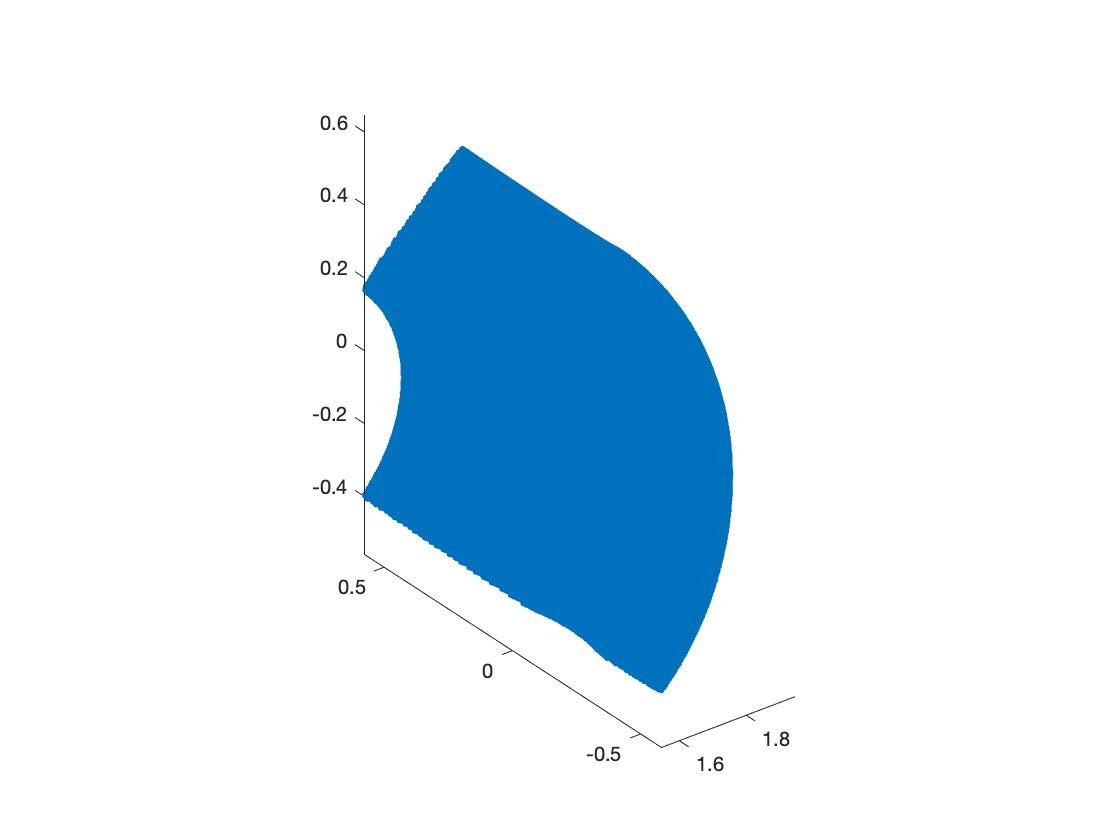

close all
point2plot=nan(3,Xdiv*Ydiv*Zdiv);
point2plot_inner=nan(3,Xdiv*Ydiv*Zdiv);
p=1;
for i = 1:Xdiv
    for j = 1:Ydiv
        for k = 1:Zdiv
            if(space_(i,j,k)==1)
                point2plot(:,p)=[X(i) Y(j) Z(k)]';
                p=p+1;
            end
        end
    end
end
plot3(point2plot(1,:),point2plot(2,:),point2plot(3,:),'.')
axis equal


save RRR_ws_dv_constrain X Xdiv Y Ydiv Z Zdiv space space_ space_empty

## 2D -> Riporto i punti sul piano e poi eseguo lo svuotamento dei punti interni per ottenere i due profili

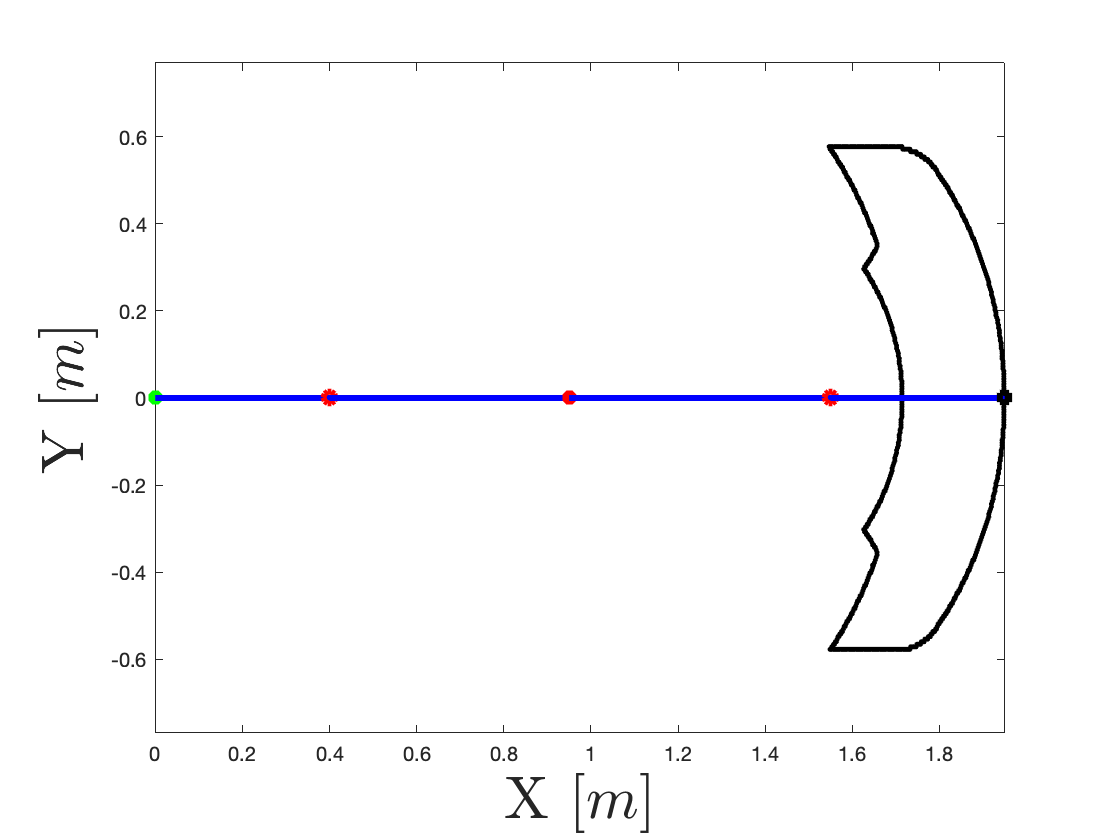

clear all
close all
load RRR_data.mat
load RRR_ws_dv_constrain.mat
space_XY=zeros(Xdiv,Ydiv);
for i = 2:Xdiv-1
    for j = 2:Ydiv-1
        for k = 2:Zdiv-1
            if(space(i,j,k)==1)
                if(space(i-1,j,k)==0 || space(i,j-1,k)==0 || space(i,j,k-1)==0 || space(i+1,j,k)==0 || space(i,j+1,k)==0 || space(i,j,k+1)==0)
                    space_XY(i,j)=1;
                end
            end
        end
    end
end
space_XY_ext=zeros(Xdiv,Ydiv);
for i = 2:Xdiv-1
    for j = 2:Ydiv-1
            if(space_XY(i,j)==1)
                if(space_XY(i-1,j)==0 || space_XY(i,j-1)==0 ||  space_XY(i+1,j)==0 || space_XY(i,j+1)==0)
                    space_XY_ext(i,j)=1;
                end
            end
    end
end
p=1;
point2plot=nan(2,Xdiv*Ydiv);
for i = 1:Xdiv
    for j = 1:Ydiv
        if(space_XY_ext(i,j)==1)
            point2plot(:,p)=[X(i) Y(j)]';
            p=p+1;
        end
    end
end
figure(1)
plot(point2plot(1,:),point2plot(2,:),'k.')
hold on
RRR_plot_cXY(link, 0, 0, 0);
axis equal
xlabel("X $[m]$","FontSize",30,"Interpreter","latex")
ylabel("Y $[m]$","FontSize",30,"Interpreter","latex")

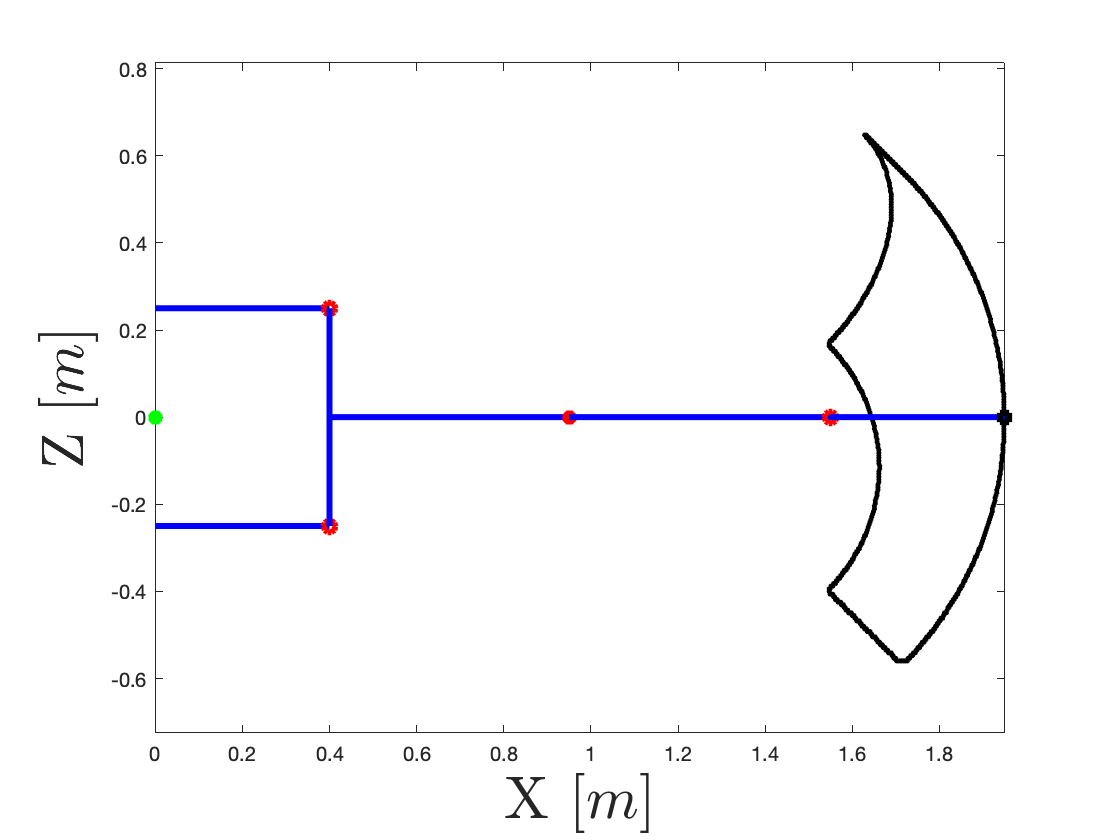



space_XZ=zeros(Xdiv,Ydiv);
for i = 2:Xdiv-1
    for j = 2:Ydiv-1
        for k = 2:Zdiv-1
            if(space(i,j,k)==1)
                if(space(i-1,j,k)==0 || space(i,j-1,k)==0 || space(i,j,k-1)==0 || space(i+1,j,k)==0 || space(i,j+1,k)==0 || space(i,j,k+1)==0)
                    space_XZ(i,k)=1;
                end
            end
        end
    end
end
space_XZ_ext=zeros(Xdiv,Zdiv);
for i = 2:Xdiv-1
    for j = 2:Zdiv-1
            if(space_XZ(i,j)==1)
                if(space_XZ(i-1,j)==0 || space_XZ(i,j-1)==0 ||  space_XZ(i+1,j)==0 || space_XZ(i,j+1)==0)
                    space_XZ_ext(i,j)=1;
                end
            end
    end
end
p=1;
point2plot=nan(2,Xdiv*Zdiv);
for i = 1:Xdiv
    for j = 1:Zdiv
        if(space_XZ_ext(i,j)==1)
            point2plot(:,p)=[X(i) Z(j)]';
            p=p+1;
        end
    end
end
figure(2)
plot(point2plot(1,:),point2plot(2,:),'k.')
hold on
RRR_plot_cXZ(link, 0, 0, 0);
axis equal
xlabel("X $[m]$","FontSize",30,"Interpreter","latex")
ylabel("Z $[m]$","FontSize",30,"Interpreter","latex")